%% Snow Mapping using Feedforward Neural Network

% --- Step 1: Load DEM and Radar Images ---
dataDir = fullfile(pwd, 'radar-images');
demfile = fullfile(pwd, 'Aletsch_SwissAlti3D_digital_elevation_model_median.tiff');

dem = double(imread(demfile));
dem(dem < 400) = NaN;
[rows, cols] = size(dem);

fileList = dir(fullfile(dataDir, 's0amp*.tiff'));
numFiles = length(fileList);
bscat = nan(rows, cols, numFiles);
dates = strings(numFiles, 1);

for i = 1:numFiles
    img = double(imread(fullfile(dataDir, fileList(i).name)));
    img(img == 0) = NaN;
    bscat(:,:,i) = (img / 255) * 20 - 13;
    dates(i) = datetime(fileList(i).name(7:16), 'InputFormat', 'yyyy-MM-dd');
end

bscat_mean = nanmean(bscat, 3);
bscat_diff = bscat - bscat_mean;

% --- Step 2: Label Pixels using Thresholding ---
threshold = -0.5;
labels_stack = bscat_diff < threshold;

% --- Step 3: Prepare Data for Neural Network ---
X = [];
Y = [];

for i = 1:numFiles
    ratio_img = bscat_diff(:,:,i);
    elevation_img = dem;
    label_img = labels_stack(:,:,i);

    valid_idx = ~isnan(ratio_img) & ~isnan(elevation_img);
    features = [ratio_img(valid_idx), elevation_img(valid_idx)];
    labels = label_img(valid_idx);

    X = [X; features];
    Y = [Y; labels];
end

% Normalize features
X = normalize(X);

% --- Step 4: Train/Test Split ---
cv = cvpartition(Y, 'HoldOut', 0.3);
X_train = X(training(cv), :)';
Y_train = Y(training(cv))';
X_test = X(test(cv), :)';
Y_test = Y(test(cv))';

% --- Step 5: Define and Train Neural Network ---
net = patternnet([10 5]);  % 2 hidden layers with 10 and 5 neurons
net.trainFcn = 'trainscg'; % Scaled conjugate gradient backpropagation
net.performFcn = 'crossentropy';

% Train the network
[net, tr] = train(net, X_train, Y_train);

% --- Step 6: Predict and Evaluate ---
Y_pred_prob = net(X_test);
Y_pred = round(Y_pred_prob);

accuracy = sum(Y_pred == Y_test) / length(Y_test);
confMat = confusionmat(Y_test, Y_pred);

fprintf('Feedforward NN Accuracy: %.2f%%\n', accuracy * 100);

Feedforward NN Accuracy: 99.99%


disp('Confusion Matrix:');

Confusion Matrix:


disp(confMat);

    16312128         450
         723     3414731



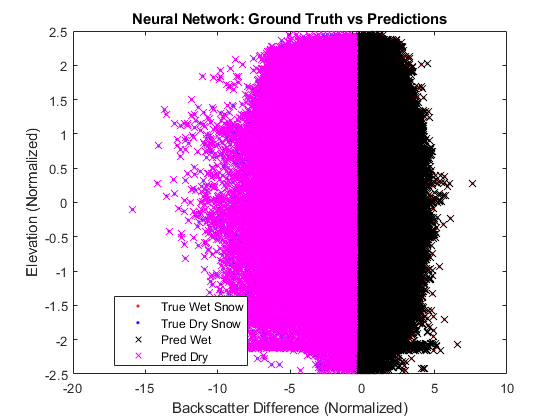


% --- Step 7: Visualization ---
figure;
gscatter(X_test(1,:), X_test(2,:), Y_test, 'rb', '..');
hold on;
gscatter(X_test(1,:), X_test(2,:), Y_pred, 'km', 'xx');
xlabel('Backscatter Difference (Normalized)');
ylabel('Elevation (Normalized)');
title('Neural Network: Ground Truth vs Predictions');
legend('True Wet Snow', 'True Dry Snow', 'Pred Wet', 'Pred Dry');
box on;
hold off;

selectedFile = 's0amp_2014-05-07HHVVcal.tiff';

radar_img = double(imread(fullfile(dataDir, selectedFile)));
radar_img(radar_img == 0) = NaN;
radar_img_dB = (radar_img / 255) * 20 - 13;
ratio_img = radar_img_dB - bscat_mean;  % Difference from mean backscatter

valid_idx = ~isnan(ratio_img) & ~isnan(dem);
X_map = [ratio_img(valid_idx), dem(valid_idx)];
X_map = normalize(X_map);  % Normalize using the same method as training

Y_pred_map = round(net(X_map'))';  % Neural net expects column-wise input

snow_map = NaN(size(dem));  % Initialize
idx_linear = find(valid_idx);  % Get linear indices of valid pixels
snow_map(idx_linear) = Y_pred_map;  % Fill classified pixels (0 = dry, 1 = wet)

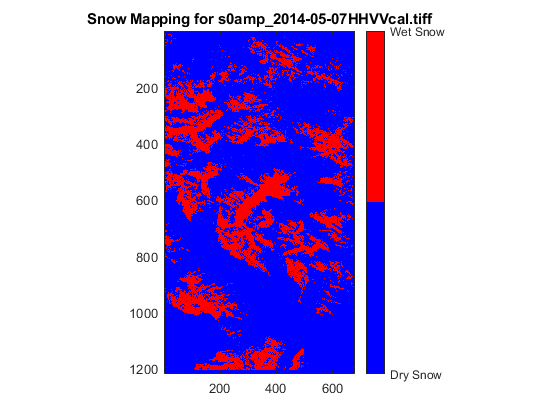

figure;
imagesc(snow_map);
colormap([0 0 1; 1 0 0]);  % Blue = dry, Red = wet
colorbar('Ticks', [0 1], 'TickLabels', {'Dry Snow', 'Wet Snow'});
title(['Snow Mapping for ', strrep(selectedFile, '_', '\_')]);
axis image;

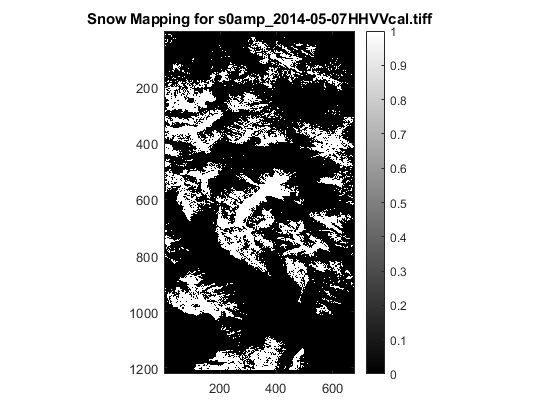

figure;
imagesc(snow_map);
colormap(gray);  % Apply grayscale colormap
colorbar;
title(['Snow Mapping for ', strrep(selectedFile, '_', '\_')]);
axis image;

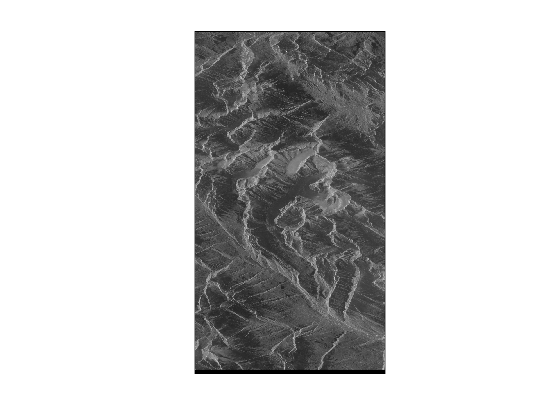

Im1 =imread('s0amp_2014-05-07HHVVcal.tiff');
imshow(Im1)

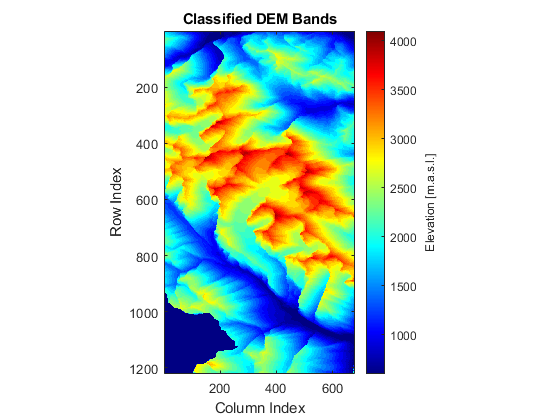

%% --- Block 2: Classify DEM height into 100m bands ---

% Define elevation classes
elev_min = 600;
elev_max = 4000;
elev_bin = 100; % Height difference between classes

% Create elevation bins
elevations = elev_min:elev_bin:(elev_max + elev_bin);
n_elev = length(elevations);

% Initialize cell array to store indices
ele_class_indices = cell(n_elev, 1);

% Initialize classified elevation matrix (for display)
elevation = nan(size(dem));

% Loop over each elevation band
for i = 1:n_elev
    % Logical index for pixels in the elevation band
    II = (dem >= elevations(i)) & (dem < (elevations(i) + elev_bin));
    
    % Store indices
    [row_idx, col_idx] = find(II);
    ele_class_indices{i} = [row_idx, col_idx];
    
    % Assign elevation value for visualization
    elevation(II) = elevations(i);
end

% Display classified DEM bands
figure;
imagesc(elevation, [600, 4100]);
colormap jet;
caxis([600 4100]);
axis image;
title('Classified DEM Bands');
xlabel('Column Index');
ylabel('Row Index');

% Add colorbar correctly
cbar = colorbar;
cbar.Label.String = 'Elevation [m.a.s.l.]';